# Demonstrates the creation of bar plots.

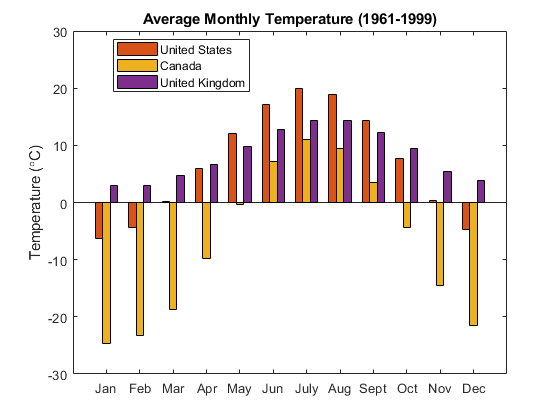

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
USA = [-6.3, -4.3, 0.1, 5.9, 12.1, 17.1, ...
       19.9, 18.9, 14.4, 7.7, 0.4, -4.8];
hb = bar(USA);
ha = gca;
    axis([0, 13, -30, 30])
    ha.XTickLabel = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', ...
                     'July', 'Aug', 'Sept', 'Oct', 'Nov', 'Dec'};
CAN = [-24.6, -23.3, -18.7, -9.8, -0.3, 7.2, ...
       11.1, 9.5, 3.5, -4.4, -14.5, -21.5];
GBR = [3.0, 3.0, 4.7, 6.7, 9.8, 12.8, ...
       14.4, 14.3, 12.2, 9.5, 5.5, 3.9];
y = [USA', CAN', GBR'];
delete(hb);
hold on
hb = bar(y);
    hb(1).BarWidth = 1.0;
    hb(2).BarWidth = 1.0;
    hb(3).BarWidth = 1.0;
title('Average Monthly Temperature (1961-1999)')
ylabel('Temperature (\circC)')
legend('United States', 'Canada', 'United Kingdom', 'Location', 'best')

# Demonstrates the creation of pie plots.

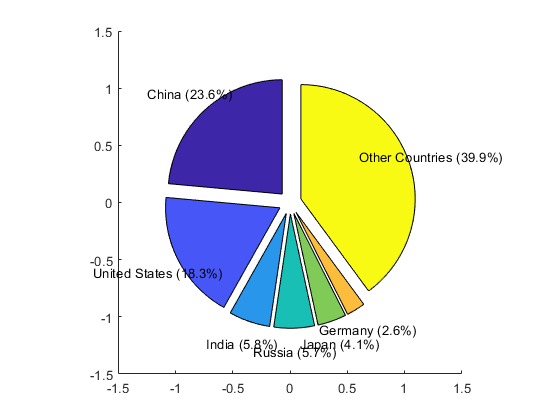

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
world = 29.85;
CHN = 7.03; USA = 5.46; IND = 1.74;
RUS = 1.71; JPN = 1.21; DEU = 0.79;
others = world - CHN - USA - IND - RUS - JPN - DEU;
x = [CHN, USA, IND, RUS, JPN, DEU, others];
explode = [1, 1, 1, 1, 1, 1, 1];
countries = {'China', 'United States', 'India', ...
    'Russia', 'Japan', 'Germany', 'Other Countries'};
for k = 1:7
    labels{k} = [countries{k}, sprintf(' (%.1f%%)', x(k)/world*100)];
end
h = pie(x, explode, labels)

    h(2).FontSize = 12;
    h(4).FontSize = 12;
    h(6).FontSize = 12;
    h(8).FontSize = 12;
    h(10).FontSize = 12;
    h(12).FontSize = 12;
    h(14).FontSize = 12;

# Creates a 3-D line plot using the parameteric equations: (pratice gradient)

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
z = linspace(0, 8*pi, 200);
x = exp(-z/20).*cos(z);
y = exp(-z/20).*sin(z);
plot3(x,y,z)
xlabel x, ylabel y, zlabel z
axis([-1, 1, -1, 1, 0, 8*pi])
h = gca; h.BoxStyle = 'full'; box on
grid on
axis vis3d

# Creates a surface in the 3-D space described by the equation z(x, y)

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = linspace(0,2*pi,100);
y = linspace(0,  pi, 50);
[X,Y] = meshgrid(x, y);
Z = sin(X) .* cos(Y);
hs = surf(X, Y, Z);
xlabel x, ylabel y, zlabel z
ha = gca;
    axis([0, 2*pi, 0, pi, -1, 1])
    ha.XTick = [0, pi/2, pi, 3*pi/2, 2*pi];
    ha.YTick = [0, pi/2, pi];
    ha.XTickLabel = {'0', '\pi/2', '\pi', '3\pi/2', '2\pi'};
    ha.YTickLabel = {'0', '\pi/2', '\pi'};
    axis vis3d
    axis equal
    ha.BoxStyle = 'full';
    box on
    grid on
colorbar
% colormap hot
%     hs.FaceAlpha = 0.2;
%     hs.EdgeColor = 'none';

# Plots a spherical surface of radius 2a centered at the origin, a cylindrical surface of radius a and length 4a, centered at (a, 0, 0), and their intersection curve given by the equations

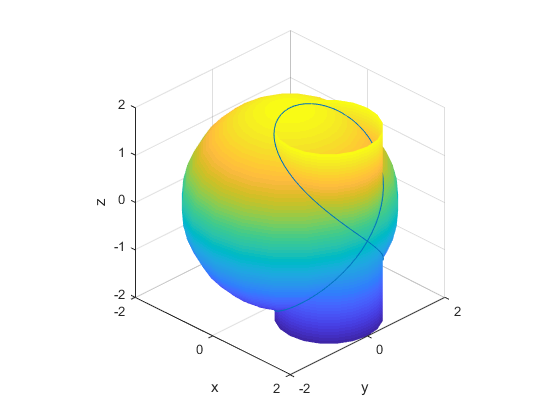

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
a = 1;
[X,Y,Z] = sphere;
surf(2*a*X,2*a*Y,2*a*Z)
hold on
[X,Y,Z] = cylinder;
surf(a*X+a,a*Y,4*a*Z-2*a)
shading interp %shading使圖像的網格曲面美觀
t = linspace(0,4*pi);
x = a*(1+cos(t));
y = a*sin(t);
z = 2*a*sin(t/2);
plot3(x,y,z)
axis equal % 設置屏幕高寬比，使得每個坐標軸的具有均勻的刻度間隔
axis vis3d % 凍結屏幕高寬比，使得一個三維對象的旋轉不會改變坐標軸的刻度顯示
xlabel x, ylabel y, zlabel z
view(45,30) % 設置Cartesian坐標系的視角  VIEW返回當前的方位角和仰角

# Demonstrates the creation of contour plots.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
[X,Y,Z] = peaks;
surf(X,Y,Z)
[C,h] = contour(X,Y,Z, [-6:8]);
% colorbar % colorbar 可以顯示高度與顏色的對照長條圖
colormap % 預設的顏色對應表可由colormap 得知
    h.ShowText = 'on';
    h.TextList = [-6:2:8];
[C,h] = contourf(X,Y,Z, [-6:8]);
clabel(C,h, [-6:2:8])
[C,h] = contour3(X,Y,Z, [-6:8]);
clabel(C,h, [-6:2:8])

# Demonstrates the creation of a 2-D vector plot.

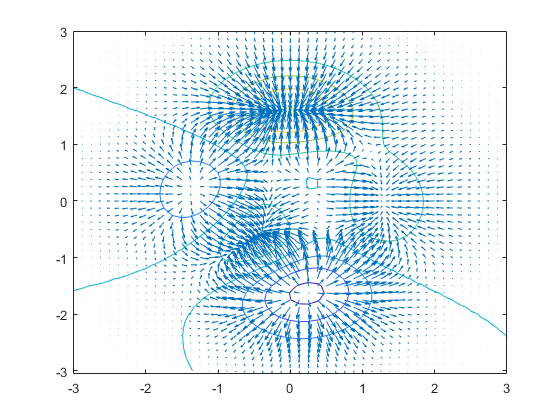

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
[X,Y,Z] = peaks;
contour(X,Y,Z); % contour 會自動找出z 的最小值及最大值，並在此範圍中找出30 個等分點，代表等高線的高度。
hold on
[U, V] = gradient(Z, 0.2, 0.2); % 具有二自變數之函數F(x,y,z) 
quiver(X, Y, U, V, 3) % 用於繪製二維矢量場圖

# Demonstrates the creation of a 3-D vector plot.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
[X,Y,Z] = peaks;
surf(X,Y,Z);
limits = axis
hold on
[U,V,W] = surfnorm(X,Y,Z);
quiver3(X, Y, Z, U, V, W) % 用法與quiver類似，用於三維矢量場圖的繪製。
axis(limits)

# Creates a 2-D streamline plot for the flow described

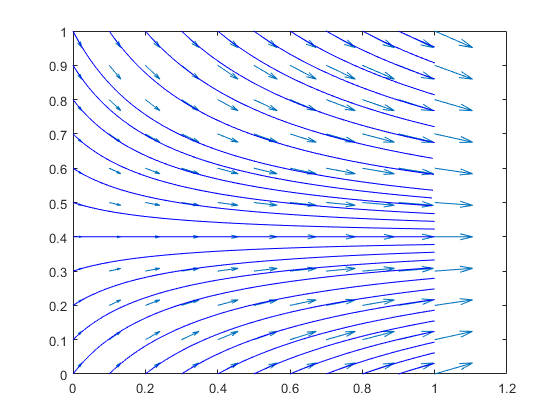

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = 0:0.1:1; y = 0:0.1:1;
[X,Y] = meshgrid(x,y);
U = 0.3+X; V = 0.4-Y;
quiver(X,Y,U,V)
sx = [0:0.1:1, zeros(1,11), 0:0.1:1];
sy = [zeros(1,11), 0:0.1:1, ones(1,11)];
SL = stream2(X,Y, U,V, sx,sy);
streamline(SL) % Plot streamlines from 2-D or 3-D vector data

# Creates a 3-D streamline plot for the flow described

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = 0:0.1:1; y = 0:0.1:1; z = 0:0.1:1;
[X,Y,Z] = meshgrid(x,y,z);
U = 0.3+X; V = 0.4-Y; W = 0.5-Z;
% quiver3(X,Y,Z,U,V,W)
sx = 0;
sy = 0:0.1:1;
sz = 0:0.1:1;
[Sx, Sy, Sz] = meshgrid(sx,sy,sz);
SL = stream3(X,Y,Z, U,V,W, Sx,Sy,Sz);
streamline(SL)
view(3), axis vis3d, box on
xlabel('x'), ylabel('y'), zlabel('z')

# Creates an isosurface plot for the potential function described

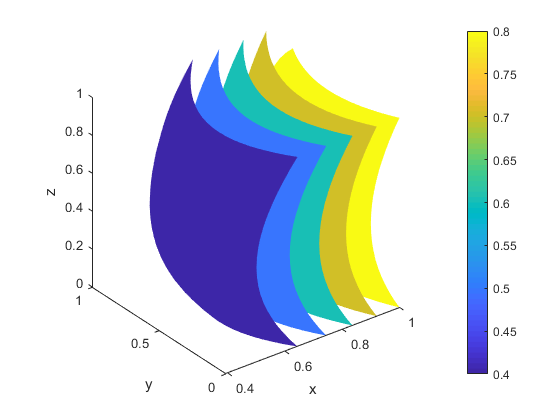

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = 0:0.05:1; y = 0:0.05:1; z = 0:0.05:1;
[X,Y,Z] = meshgrid(x,y,z);
V = 0.3*X+0.4*Y+0.5*Z+0.5*X.^2-0.5*Y.^2-0.5*Z.^2;
colorbar
hold on
for isovalue = 0.4:0.1:0.8
    isosurface(X,Y,Z,V, isovalue) % ??函?的等值曲?或曲面. 如?笛卡?心形函?
end
view(3), axis vis3d
xlabel('x'), ylabel('y'), zlabel('z')